## Selected Topics in Power Systems

## Coursework for "Power Electronics in Distribution Networks"

**Authors:** Ruiyu Zhang

**Date: 8** November 2025

### Question 1:

Calculate the voltages of nodes (1), (2), (3) and (4) and the current of the different sections of  the feeders for the loading that corresponds to Monday at 11 am. Are the voltages within the  statutory range? Are the currents below their thermal rating (ie 1.2 pu)?

clear; clc;

% Slack bus
V1 = 1.01;             % |V1|, angle=0

% Specified injections (pu), generation +, load -
P2s = +0.85;  Q2s = 0.0;
P3s = -0.01;  Q3s = 0.0;
P4s = -0.5;   Q4s = -0.1;

% Branch impedances (pu, resistive)
Z12 = 0.04 + 0j;
Z23 = 0.02 + 0j;
Z14 = 0.04 + 0j;

Y12 = 1/Z12; Y23 = 1/Z23; Y14 = 1/Z14;

% Conductance coefficients (from Ybus)
G21 = -25; G22 = 75; G23 = -50;
G32 = -50; G33 = 50;
G41 = -25; G44 = 25;

% Pcalc and Qcalc for buses 2,3,4
Pcalc = @(V2,V3,V4,t2,t3,t4) [...
    V2*V1*G21*cos(t2) + V2^2*G22 + V2*V3*G23*cos(t2 - t3);...
    V3*V2*G32*cos(t3 - t2) + V3^2*G33;...
    V4*V1*G41*cos(t4) + V4^2*G44 ];

Qcalc = @(V2,V3,V4,t2,t3,t4) [...
    V2*V1*G21*sin(t2) + V2*V3*G23*sin(t2 - t3);...
    V3*V2*G32*sin(t3 - t2);...
    V4*V1*G41*sin(t4) ];

% Mismatch vector F(x) = [Pcalc-Pspec; Qcalc-Qspec] (6x1 column)
f = @(x) [...
    Pcalc(x(4),x(5),x(6),x(1),x(2),x(3)) - [P2s; P3s; P4s];...
    Qcalc(x(4),x(5),x(6),x(1),x(2),x(3)) - [Q2s; Q3s; Q4s] ];

% Hand-written Jacobian J(x): 6x6
J = @(x) jacobian_hand(V1, G21,G22,G23,G32,G33,G41,G44, x);

function Jm = jacobian_hand(V1,G21,G22,G23,G32,G33,G41,G44, x)
    t2=x(1); t3=x(2); t4=x(3); V2=x(4); V3=x(5); V4=x(6);

    % H = dP/dtheta
    H22 = 25*V1*V2*sin(t2) + 50*V2*V3*sin(t2 - t3);
    H23 = -50*V2*V3*sin(t2 - t3);
    H24 = 0;

    H32 = -50*V2*V3*sin(t3 - t2);
    H33 =  50*V2*V3*sin(t3 - t2);
    H34 = 0;

    H42 = 0; H43 = 0; H44 = 25*V1*V4*sin(t4);

    % N = dP/d|V|
    N22 = 150*V2 - 25*V1*cos(t2) - 50*V3*cos(t2 - t3);
    N23 = -50*V2*cos(t2 - t3);
    N24 = 0;

    N32 = -50*V3*cos(t3 - t2);
    N33 = 100*V3 - 50*V2*cos(t3 - t2);
    N34 = 0;

    N42 = 0; N43 = 0; N44 = 50*V4 - 25*V1*cos(t4);

    % M = dQ/dtheta
    M22 = -25*V1*V2*cos(t2) - 50*V2*V3*cos(t2 - t3);
    M23 =  50*V2*V3*cos(t2 - t3);
    M24 =  0;

    M32 =  50*V2*V3*cos(t3 - t2);
    M33 = -50*V2*V3*cos(t3 - t2);
    M34 =  0;

    M42 = 0; M43 = 0; M44 = -25*V1*V4*cos(t4);

    % L = dQ/d|V|
    L22 = -25*V1*sin(t2) - 50*V3*sin(t2 - t3);
    L23 = -50*V2*sin(t2 - t3);
    L24 = 0;

    L32 = -50*V3*sin(t3 - t2);
    L33 = -50*V2*sin(t3 - t2);
    L34 = 0;

    L42 = 0; L43 = 0; L44 = -25*V1*sin(t4);

    Jm = [...
        H22, H23, H24, N22, N23, N24;
        H32, H33, H34, N32, N33, N34;
        H42, H43, H44, N42, N43, N44;
        M22, M23, M24, L22, L23, L24;
        M32, M33, M34, L32, L33, L34;
        M42, M43, M44, L42, L43, L44 ];
end
fprintf('\nTask1 Solution\n');


Task1 Solution


% Newton iterations: x = [t2; t3; t4; V2; V3; V4]
x   = [0; 0; 0; 1.0; 1.0; 1.0];    % column vector
tol = 1e-10; maxIt = 100;

for k = 1:maxIt
    F  = f(x);                    % 6x1 column
    if norm(F, inf) < tol, break; end
    Jm = J(x);                    % 6x6
    dx = - Jm \ F;                % Newton step
    x  = x + dx;                  % update (column arithmetic)
    fprintf('Iter %2d, ||F||_inf = %.3e\n', k, norm(F, inf));
end

Iter  1, ||F||_inf = 1.100e+00
Iter  2, ||F||_inf = 4.893e-02
Iter  3, ||F||_inf = 8.165e-05
Iter  4, ||F||_inf = 2.289e-10



% Compose voltages
t2=x(1); t3=x(2); t4=x(3); V2=x(4); V3=x(5); V4=x(6);
V = [V1*exp(1j*0); V2*exp(1j*t2); V3*exp(1j*t3); V4*exp(1j*t4)];

% Branch currents
I12 = Y12*(V(1)-V(2));
I23 = Y23*(V(2)-V(3));
I14 = Y14*(V(1)-V(4));


for i=1:4
    fprintf('Bus %d: |V|=%.6f pu, angle=%.4f deg\n', i, abs(V(i)), rad2deg(angle(V(i))));
end

Bus 1: |V|=1.010000 pu, angle=0.0000 deg
Bus 2: |V|=1.042238 pu, angle=0.0000 deg
Bus 3: |V|=1.042046 pu, angle=0.0000 deg
Bus 4: |V|=0.989786 pu, angle=0.2293 deg


fprintf('Line currents: |I12|=%.5f, |I23|=%.5f, |I14|=%.5f pu\n', abs(I12), abs(I23), abs(I14));

Line currents: |I12|=0.80596, |I23|=0.00960, |I14|=0.51516 pu



inRange   = (abs(V)>=0.96) & (abs(V)<=1.04);
thermalOK = [abs(I12)<1.2, abs(I23)<1.2, abs(I14)<1.2];
fprintf('Voltage in-range flags: '); fprintf('%d ', inRange); fprintf('\n');

Voltage in-range flags: 1 0 0 1 


fprintf('Thermal check (<1.2 pu): %d %d %d\n', thermalOK);

Thermal check (<1.2 pu): 1 1 1


### Question 2:

Consider the future scenario where a SOP is connected between Buses 3 and 4 plot the  voltage of all the buses for a range of power setpoints of the SOP going from -1 pu to 1 pu of  active power (at zero reactive power on both sides) for Monday at 11 am. What range of  active power keeps the voltage of Bus 3 within the statutory range?

clear; clc;

%% ----------- Network data (per-unit) -----------------------
V1  = 1.01;              % Slack magnitude (angle = 0 rad)
Z12 = 0.04 + 0j;
Z23 = 0.02 + 0j;
Z14 = 0.04 + 0j;

% Build Ybus directly (no helper functions)
Ybus = zeros(4,4);
Y12  = 1/Z12;  Y23 = 1/Z23;  Y14 = 1/Z14;

% Branch 1-2
Ybus(1,1) = Ybus(1,1) + Y12;  Ybus(2,2) = Ybus(2,2) + Y12;
Ybus(1,2) = Ybus(1,2) - Y12;  Ybus(2,1) = Ybus(2,1) - Y12;
% Branch 2-3
Ybus(2,2) = Ybus(2,2) + Y23;  Ybus(3,3) = Ybus(3,3) + Y23;
Ybus(2,3) = Ybus(2,3) - Y23;  Ybus(3,2) = Ybus(3,2) - Y23;
% Branch 1-4
Ybus(1,1) = Ybus(1,1) + Y14;  Ybus(4,4) = Ybus(4,4) + Y14;
Ybus(1,4) = Ybus(1,4) - Y14;  Ybus(4,1) = Ybus(4,1) - Y14;

G = real(Ybus);   % B ≈ 0 in this coursework

% Conductance entries used by hand-written formulas
G21 = G(2,1); G22 = G(2,2); G23 = G(2,3);
G32 = G(3,2); G33 = G(3,3);
G41 = G(4,1); G44 = G(4,4);

%% ----------- Base injections (no SOP) ----------------------
% Generation +, load - (Monday 11am scenario)
P2s_base = +0.85;  Q2s_base = 0.0;
P3s_base = -0.01;  Q3s_base = 0.0;
P4s_base = -0.5;   Q4s_base = -0.1;

%% ----------- NR solver with hand-written Jacobian ----------
% Variable order: x = [t2; t3; t4; V2; V3; V4]
solveNR = @(P2s,P3s,P4s,Q2s,Q3s,Q4s) NR_hand(V1,...
    G21,G22,G23,G32,G33,G41,G44, P2s,P3s,P4s,Q2s,Q3s,Q4s);

%% ----------- SOP sweep: Pt ∈ [-1, 1] -----------------------
Pts   = linspace(-1, 1, 41);             % step 0.05
Vmag  = zeros(4, numel(Pts));            % store |V| for buses 1..4

for k = 1:numel(Pts)
    Pt = Pts(k);
    % SOP modifies specified active power at buses 3 and 4 (Q unchanged)
    P2s = P2s_base;    Q2s = Q2s_base;
    P3s = P3s_base - Pt;  Q3s = Q3s_base;    % draw at Bus 3
    P4s = P4s_base + Pt;  Q4s = Q4s_base;    % inject at Bus 4

    [V, ~] = solveNR(P2s,P3s,P4s,Q2s,Q3s,Q4s);
    Vmag(:,k) = abs(V);
end

% Determine valid Pt range for Bus 3 voltage
ok3 = (Vmag(3,:) >= 0.96) & (Vmag(3,:) <= 1.04);
if any(ok3)
    Pt_valid = [min(Pts(ok3)), max(Pts(ok3))];
else
    Pt_valid = [NaN, NaN];
end


%% ----------- Plot voltages vs Pt ---------------------------
fprintf('\nTask2 Solution\n');


Task2 Solution


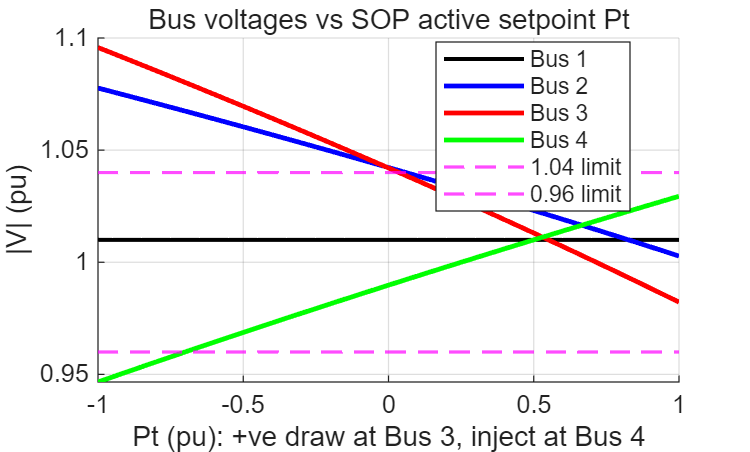

figure; hold on; grid on;
plot(Pts, Vmag(1,:), 'k-',  'LineWidth', 1.5);   % Bus 1
plot(Pts, Vmag(2,:), 'b-',  'LineWidth', 1.8);   % Bus 2
plot(Pts, Vmag(3,:), 'r-',  'LineWidth', 1.8);   % Bus 3
plot(Pts, Vmag(4,:), 'g-',  'LineWidth', 1.8);   % Bus 4
yline(1.04, 'm--', 'LineWidth', 1.2); yline(0.96, 'm--', 'LineWidth', 1.2);
xlabel('Pt (pu): +ve draw at Bus 3, inject at Bus 4');
ylabel('|V| (pu)');
legend('Bus 1','Bus 2','Bus 3','Bus 4','1.04 limit','0.96 limit','Location','best');
title('Bus voltages vs SOP active setpoint Pt');


fprintf('\nValid Pt range keeping |V3| in [0.96, 1.04]: [%.3f, %.3f] pu\n', Pt_valid(1), Pt_valid(2));


Valid Pt range keeping |V3| in [0.96, 1.04]: [0.050, 1.000] pu



%% ----------- Optional: inspect currents at a chosen Pt -----
Pt_inspect = 0.40;  % example
P2s = P2s_base; Q2s = Q2s_base;
P3s = P3s_base - Pt_inspect; Q3s = Q3s_base;
P4s = P4s_base + Pt_inspect; Q4s = Q4s_base;
[V, ~] = solveNR(P2s,P3s,P4s,Q2s,Q3s,Q4s);

I12 = Y12*(V(1)-V(2));
I23 = Y23*(V(2)-V(3));
I14 = Y14*(V(1)-V(4));
fprintf('At Pt=%.2f: |V|=[%.4f %.4f %.4f %.4f], |I12|=%.4f, |I23|=%.4f, |I14|=%.4f\n',...
    Pt_inspect, abs(V(1)), abs(V(2)), abs(V(3)), abs(V(4)), abs(I12), abs(I23), abs(I14));

At Pt=0.40: |V|=[1.0100 1.0270 1.0190 1.0060], |I12|=0.4253, |I23|=0.4024, |I14|=0.1406



% ===================== Local functions ======================
function [V, iter] = NR_hand(V1,G21,G22,G23,G32,G33,G41,G44,...
                             P2s,P3s,P4s,Q2s,Q3s,Q4s)
    % Hand-written P,Q (B≈0)
    Pcalc = @(V2,V3,V4,t2,t3,t4) [...
        V2*V1*G21*cos(t2) + V2^2*G22 + V2*V3*G23*cos(t2 - t3);...
        V3*V2*G32*cos(t3 - t2) + V3^2*G33;...
        V4*V1*G41*cos(t4) + V4^2*G44 ];
    Qcalc = @(V2,V3,V4,t2,t3,t4) [...
        V2*V1*G21*sin(t2) + V2*V3*G23*sin(t2 - t3);...
        V3*V2*G32*sin(t3 - t2);...
        V4*V1*G41*sin(t4) ];

    f = @(x) [...
        Pcalc(x(4),x(5),x(6),x(1),x(2),x(3)) - [P2s; P3s; P4s];...
        Qcalc(x(4),x(5),x(6),x(1),x(2),x(3)) - [Q2s; Q3s; Q4s] ];

    J = @(x) jacobian_hand(V1, G21,G22,G23,G32,G33,G41,G44, x);

    % Newton iterations
    x   = [0; 0; 0; 1.0; 1.0; 1.0];  % flat start
    tol = 1e-10; maxIt = 100;
    for iter = 1:maxIt
        F  = f(x);
        if norm(F, inf) < tol, break; end
        Jm = J(x);
        dx = - Jm \ F;
        x  = x + dx;
    end

    % Compose complex voltages
    t2=x(1); t3=x(2); t4=x(3); V2=x(4); V3=x(5); V4=x(6);
    V = [V1*exp(1j*0); V2*exp(1j*t2); V3*exp(1j*t3); V4*exp(1j*t4)];
end

function Jm = jacobian_hand2(V1,G21,G22,G23,G32,G33,G41,G44, x)
    t2=x(1); t3=x(2); t4=x(3); V2=x(4); V3=x(5); V4=x(6);

    % H = dP/dtheta (general form with G)
    H22 = -V2*V1*G21*sin(t2) - V2*V3*G23*sin(t2 - t3);
    H23 =  +V2*V3*G23*sin(t2 - t3);
    H24 = 0;

    H32 =  +V2*V3*G32*sin(t3 - t2);
    H33 =  -V2*V3*G32*sin(t3 - t2);
    H34 = 0;

    H42 = 0; H43 = 0;
    H44 = -V4*V1*G41*sin(t4);

    % N = dP/d|V|
    N22 = 2*V2*G22 + V1*G21*cos(t2) + V3*G23*cos(t2 - t3);
    N23 = V2*G23*cos(t2 - t3);
    N24 = 0;

    N32 = V3*G32*cos(t3 - t2);
    N33 = 2*V3*G33 + V2*G32*cos(t3 - t2);
    N34 = 0;

    N42 = 0; N43 = 0;
    N44 = 2*V4*G44 + V1*G41*cos(t4);

    % M = dQ/dtheta
    M22 =  V2*V1*G21*cos(t2) + V2*V3*G23*cos(t2 - t3);
    M23 = -V2*V3*G23*cos(t2 - t3);
    M24 = 0;

    M32 = -V2*V3*G32*cos(t3 - t2);
    M33 =  V2*V3*G32*cos(t3 - t2);
    M34 = 0;

    M42 = 0; M43 = 0;
    M44 =  V4*V1*G41*cos(t4);

    % L = dQ/d|V|
    L22 =  V1*G21*sin(t2) + V3*G23*sin(t2 - t3);
    L23 =  V2*G23*sin(t2 - t3);
    L24 = 0;

    L32 =  V3*G32*sin(t3 - t2);
    L33 =  V2*G32*sin(t3 - t2);
    L34 = 0;

    L42 = 0; L43 = 0;
    L44 =  V1*G41*sin(t4);

    % Assemble Jacobian: rows [P2 P3 P4 Q2 Q3 Q4], cols [t2 t3 t4 V2 V3 V4]
    Jm = [...
        H22, H23, H24, N22, N23, N24;
        H32, H33, H34, N32, N33, N34;
        H42, H43, H44, N42, N43, N44;
        M22, M23, M24, L22, L23, L24;
        M32, M33, M34, L32, L33, L34;
        M42, M43, M44, L42, L43, L44 ];
end

### Question 3:

Consider the operation point of the SOP where it draws 0.4 pu from Bus 3 and feeds it to Bus  4. Would any voltage limit be breached if the generator in Bus 2 was disconnected suddenly? 

clear; clc;

%% ----------- Network data (per-unit, resistive) ------------
V1  = 1.01;              % Slack magnitude, angle = 0
Z12 = 0.04 + 0j;
Z23 = 0.02 + 0j;
Z14 = 0.04 + 0j;

% Build Ybus directly
Ybus = zeros(4,4);
Y12 = 1/Z12; Y23 = 1/Z23; Y14 = 1/Z14;

% Branch 1-2
Ybus(1,1)=Ybus(1,1)+Y12; Ybus(2,2)=Ybus(2,2)+Y12;
Ybus(1,2)=Ybus(1,2)-Y12; Ybus(2,1)=Ybus(2,1)-Y12;
% Branch 2-3
Ybus(2,2)=Ybus(2,2)+Y23; Ybus(3,3)=Ybus(3,3)+Y23;
Ybus(2,3)=Ybus(2,3)-Y23; Ybus(3,2)=Ybus(3,2)-Y23;
% Branch 1-4
Ybus(1,1)=Ybus(1,1)+Y14; Ybus(4,4)=Ybus(4,4)+Y14;
Ybus(1,4)=Ybus(1,4)-Y14; Ybus(4,1)=Ybus(4,1)-Y14;

G = real(Ybus);                % B≈0 for this coursework

% Conductance entries used by hand-written formulas
G21 = G(2,1); G22 = G(2,2); G23 = G(2,3);
G32 = G(3,2); G33 = G(3,3);
G41 = G(4,1); G44 = G(4,4);

%% ----------- Scenario: Pt=0.4 and generator at Bus 2 trips --
Pt  = 0.4;

% Specified injections (generation +, load -)
P2s = 0.0;   Q2s = 0.0;             % generator tripped
P3s = -0.01 - Pt;  Q3s = 0.0;       % SOP draws at Bus 3
P4s = -0.5  + Pt;  Q4s = -0.1;      % SOP feeds at Bus 4

%% ----------- Solve with hand-written NR ---------------------
[V, iter] = NR_hand(V1, G21,G22,G23,G32,G33,G41,G44, P2s,P3s,P4s,Q2s,Q3s,Q4s);

% Branch currents and checks
I12 = Y12*(V(1)-V(2));
I23 = Y23*(V(2)-V(3));
I14 = Y14*(V(1)-V(4));
fprintf('\nTask3 Solution\n');


Task3 Solution


fprintf('--- Contingency result (Pt=0.4, Bus2 trip) ---\n');

--- Contingency result (Pt=0.4, Bus2 trip) ---


for i=1:4
    fprintf('Bus %d: |V|=%.6f pu, angle=%.4f deg\n', i, abs(V(i)), rad2deg(angle(V(i))));
end

Bus 1: |V|=1.010000 pu, angle=0.0000 deg
Bus 2: |V|=0.993351 pu, angle=0.0000 deg
Bus 3: |V|=0.985026 pu, angle=0.0000 deg
Bus 4: |V|=1.006016 pu, angle=0.2256 deg


fprintf('Line currents: |I12|=%.5f, |I23|=%.5f, |I14|=%.5f pu\n', abs(I12), abs(I23), abs(I14));

Line currents: |I12|=0.41623, |I23|=0.41623, |I14|=0.14058 pu



% Statutory voltage range check
inRange = (abs(V)>=0.96) & (abs(V)<=1.04);
fprintf('Voltage statutory in-range flags [B1 B2 B3 B4]: ');

Voltage statutory in-range flags [B1 B2 B3 B4]: 

fprintf('%d ', inRange); fprintf('\n');

1 1 1 1 



% Thermal check (<1.2 pu)
thermalOK = [abs(I12)<1.2, abs(I23)<1.2, abs(I14)<1.2];
fprintf('Thermal check (<1.2 pu): %d %d %d\n', thermalOK);

Thermal check (<1.2 pu): 1 1 1



% ===================== Local functions ======================
function [V, iter] = NR_hand3(V1,G21,G22,G23,G32,G33,G41,G44,...
                             P2s,P3s,P4s,Q2s,Q3s,Q4s)
    % Hand-written P,Q (B≈0)
    Pcalc = @(V2,V3,V4,t2,t3,t4) [...
        V2*V1*G21*cos(t2) + V2^2*G22 + V2*V3*G23*cos(t2 - t3);...
        V3*V2*G32*cos(t3 - t2) + V3^2*G33;...
        V4*V1*G41*cos(t4) + V4^2*G44 ];
    Qcalc = @(V2,V3,V4,t2,t3,t4) [...
        V2*V1*G21*sin(t2) + V2*V3*G23*sin(t2 - t3);...
        V3*V2*G32*sin(t3 - t2);...
        V4*V1*G41*sin(t4) ];

    f = @(x) [...
        Pcalc(x(4),x(5),x(6),x(1),x(2),x(3)) - [P2s; P3s; P4s];...
        Qcalc(x(4),x(5),x(6),x(1),x(2),x(3)) - [Q2s; Q3s; Q4s] ];

    J = @(x) jacobian_hand(V1, G21,G22,G23,G32,G33,G41,G44, x);

    % Newton iterations
    x   = [0; 0; 0; 1.0; 1.0; 1.0];  % flat start
    tol = 1e-10; maxIt = 100;
    for iter = 1:maxIt
        F  = f(x);
        if norm(F, inf) < tol, break; end
        Jm = J(x);
        dx = - Jm \ F;
        x  = x + dx;
    end

    % Compose complex voltages
    t2=x(1); t3=x(2); t4=x(3); V2=x(4); V3=x(5); V4=x(6);
    V = [V1*exp(1j*0); V2*exp(1j*t2); V3*exp(1j*t3); V4*exp(1j*t4)];
end

function Jm = jacobian_hand3(V1,G21,G22,G23,G32,G33,G41,G44, x)
    t2=x(1); t3=x(2); t4=x(3); V2=x(4); V3=x(5); V4=x(6);

    % H = dP/dtheta
    H22 = -V2*V1*G21*sin(t2) - V2*V3*G23*sin(t2 - t3);
    H23 =  +V2*V3*G23*sin(t2 - t3);
    H24 = 0;

    H32 =  +V2*V3*G32*sin(t3 - t2);
    H33 =  -V2*V3*G32*sin(t3 - t2);
    H34 = 0;

    H42 = 0; H43 = 0;
    H44 = -V4*V1*G41*sin(t4);

    % N = dP/d|V|
    N22 = 2*V2*G22 + V1*G21*cos(t2) + V3*G23*cos(t2 - t3);
    N23 = V2*G23*cos(t2 - t3);
    N24 = 0;

    N32 = V3*G32*cos(t3 - t2);
    N33 = 2*V3*G33 + V2*G32*cos(t3 - t2);
    N34 = 0;

    N42 = 0; N43 = 0;
    N44 = 2*V4*G44 + V1*G41*cos(t4);

    % M = dQ/dtheta
    M22 =  V2*V1*G21*cos(t2) + V2*V3*G23*cos(t2 - t3);
    M23 = -V2*V3*G23*cos(t2 - t3);
    M24 = 0;

    M32 = -V2*V3*G32*cos(t3 - t2);
    M33 =  V2*V3*G32*cos(t3 - t2);
    M34 = 0;

    M42 = 0; M43 = 0;
    M44 =  V4*V1*G41*cos(t4);

    % L = dQ/d|V|
    L22 =  V1*G21*sin(t2) + V3*G23*sin(t2 - t3);
    L23 =  V2*G23*sin(t2 - t3);
    L24 = 0;

    L32 =  V3*G32*sin(t3 - t2);
    L33 =  V2*G32*sin(t3 - t2);
    L34 = 0;

    L42 = 0; L43 = 0;
    L44 =  V1*G41*sin(t4);

    % Assemble Jacobian: rows [P2 P3 P4 Q2 Q3 Q4], cols [t2 t3 t4 V2 V3 V4]
    Jm = [...
        H22, H23, H24, N22, N23, N24;
        H32, H33, H34, N32, N33, N34;
        H42, H43, H44, N42, N43, N44;
        M22, M23, M24, L22, L23, L24;
        M32, M33, M34, L32, L33, L34;
        M42, M43, M44, L42, L43, L44 ];
end